## Initial setup

clear
currentFolder = fileparts(matlab.desktop.editor.getActiveFilename);
% Load src, data and utils folders
addpath(fullfile(currentFolder, 'src'));
dataFolder = fullfile(currentFolder, 'data');
addpath(dataFolder);
addpath(fullfile(currentFolder, 'utils'));

## Load data from zone_id

%zoneId=1;  %"Zone_509_Ponte Mammolo";
%zoneId=2;  %"Zone_116_Trastevere";
%zoneId=3;  %"Zone_125";
%zoneId=4;  %"Zone_705_Prenestino-Centocelle";;
%zoneId=5;  %"Eur 1201"
%zoneId=6;
%zoneId=7;  %"Zone_906_Arco_Di_Travertino"
%zoneId=8;  % Zona 1016
%zoneId=9;  %Zona 214 Trieste
%zoneId=10; % Zona 2004
zoneId=11; % Zona 2002
%zoneId=12; %Torvergata
fprintf("zoneId selected: %d \n", zoneId);

zoneId selected: 11 


zoneData = loadZoneData(dataFolder, zoneId);

Data for zone "Zone2002_Tor di Quinto6" loaded correctly (2784 rows x 17 columns).


Add cyclic hour feature to encode the 24-hour periodic rhythm

hours = hour(zoneData.datetime) + minute(zoneData.datetime)/60;
zoneData.cosHour = cos(2 * pi * hours / 24);
zoneData.sinHour = sin(2 * pi * hours / 24);

## Variables and constants

windowSize = 48; % 24 hours lookback
targetName = "AAC_energy";  % One-step-ahead prediction target (t+1)
predictorNames = [ ...
    "AAC_energy", ...
    "temp", ...
    "windspeed" ...
    "cosHour", ...
    "sinHour", ...
    ];

numFeatures = numel(predictorNames);
fprintf("Windows size: %d \n", windowSize);

Windows size: 48 


fprintf("Number of features: %d \n", numFeatures);

Number of features: 5 


fprintf("Target variable: %s\n", targetName);

Target variable: AAC_energy


## Split datas into train, validation and test

[trainData, valData, testData, normParams] = splitZoneData(zoneData, windowSize, predictorNames, targetName);

Split completed: 1824 train, 384 val, 384 test samples.


## Feature Selection: Linear Correlation and Cross-Correlation Analysis

Calculate the linear correlation between each candidate predictor and charging energy demand to identify redundant or uninformative variables.

candidateFeatures = [ ...
    "AAC_energy", ...
    "temp", ...
    "feelslike", ...
    "humidity", ...
    "precip", ...
    "precipprob", ...
    "windspeed", ...
    "cosHour", ...
    "sinHour", ...
    "holiday_proximity"];
corrMatrix = corr(zoneData{:, candidateFeatures}, Rows="complete");
disp(table(candidateFeatures', round(corrMatrix(:,1), 4), ...
    VariableNames=["Feature", "Correlation"]))

          Feature          Correlation
    ___________________    ___________

    "AAC_energy"                   1  
    "temp"                    0.1841  
    "feelslike"               0.1735  
    "humidity"               -0.4265  
    "precip"                  0.0005  
    "precipprob"              0.0071  
    "windspeed"               0.2764  
    "cosHour"                -0.6904  
    "sinHour"                 -0.284  
    "holiday_proximity"      -0.1449  



Compute the sample cross-correlation between ambient temperature and energy demand to check for physical thermal lag.

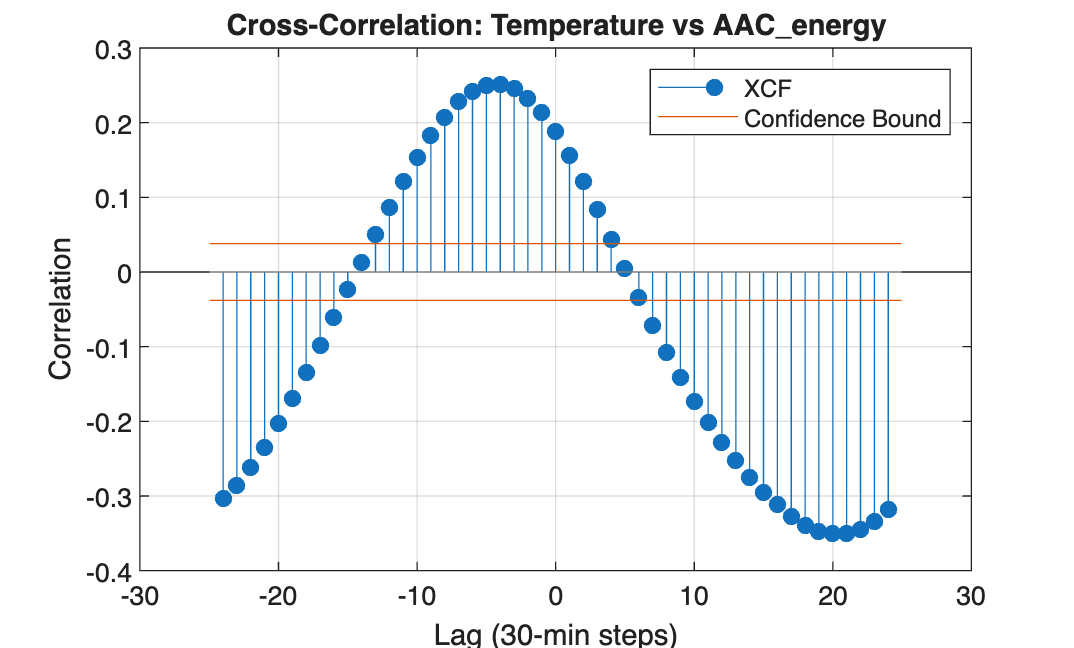

figure
crosscorr(zoneData.temp, zoneData.AAC_energy, NumLags=24)
title("Cross-Correlation: Temperature vs AAC\_energy")
xlabel("Lag (30-min steps)")
ylabel("Correlation")
grid on

## Prepare the data for the LSTM

Using this guide [https://it.mathworks.com/help/deeplearning/ug/time-series-forecasting-using-deep-learning.html](https://it.mathworks.com/help/deeplearning/ug/time-series-forecasting-using-deep-learning.html)

XTrain = trainData.X;
TTrain = trainData.T;
XVal = valData.X;
TVal = valData.T;
XTest = testData.X;
TTest = testData.T;
numChannels = size(XTrain{1}, 2);
fprintf("Input channels: %d\n", numChannels);

Input channels: 5


fprintf("Training sequences:   %d\n", numel(XTrain));

Training sequences:   1824


fprintf("Validation sequences: %d\n", numel(XVal));

Validation sequences: 384


fprintf("Test sequences:       %d\n", numel(XTest));

Test sequences:       384


## Specify Training Options

Specify the training options. Choosing among the options requires empirical analysis. To explore different training option configurations by running experiments, you can use the [Experiment Manager](docid:nnet_ref.mw_11ce840f-eed7-4975-9c28-baeebd79f092) app.

- Train using Adam optimization.

- Train for 200 epochs. For larger data sets, you might not need to train for as many epochs for a good fit.

- In each mini-batch, left-pad the sequences so they have the same length. Left-padding prevents the RNN from predicting padding values at the ends of sequences.

- Shuffle the data every epoch.

- Display the training progress in a plot.

- Disable the verbose output.

netOptions = trainingOptions("adam", ...
    MaxEpochs=100, ...
    MiniBatchSize=64, ...
    ValidationData={XVal, TVal}, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false);

## Define LSTM Neural Network Architecture

Create an LSTM regression neural network.

- Use a sequence input layer with an input size that matches the number of channels of the input data. Normalize the input data using *Z*-score normalization.

- Use an LSTM layer with 48 hidden units (the information of one day). The number of hidden units determines how much information is learned by the layer. Using more hidden units can yield more accurate results but can be more likely to lead to overfitting to the training data

Use the Deep Network Designer to design the net

netLayers = [
    sequenceInputLayer(numChannels,"Name","input")
    lstmLayer(64,"Name","lstm","OutputMode","last")
    dropoutLayer(0.5,"Name","dropout")
    fullyConnectedLayer(1,"Name","AAC_energy")];

## Train Recurrent Neural Network

Train the LSTM neural network using the [`trainnet`](docid:nnet_ref.mw_87a4761c-af20-4e6e-9752-e145a8295c97) function. For regression, use mean squared error (MSE) loss.

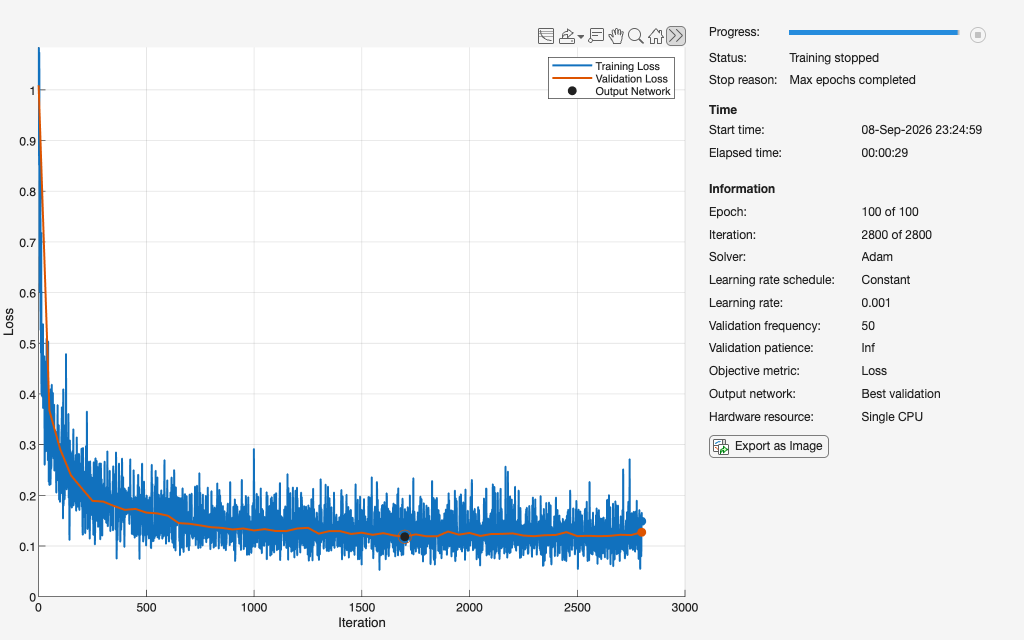

LSTMnet = trainnet(XTrain,TTrain,netLayers,"mse",netOptions);

## Test our net

Generate predictions on the test sequences using the trained network. Left-padding aligns the sequence ends with the targets.

YTestNorm = minibatchpredict(LSTMnet, XTest, SequencePaddingDirection="left");

Rescale predictions and true targets back to physical kilowatt-hours using the training baseline parameters.

YTest = YTestNorm .* normParams.sigmaTarget + normParams.muTarget;
TTestReal = TTest .* normParams.sigmaTarget + normParams.muTarget;

Evaluate model accuracy using root mean squared error and mean absolute error.

testRMSE = rmse(YTest, TTestReal);
testMAE = mean(abs(YTest - TTestReal));
fprintf("Test RMSE: %.2f kWh\n", testRMSE);

Test RMSE: 95.80 kWh


fprintf("Test MAE:  %.2f kWh\n", testMAE);

Test MAE:  69.32 kWh


Plot the real charging load against the network predictions across the test period.

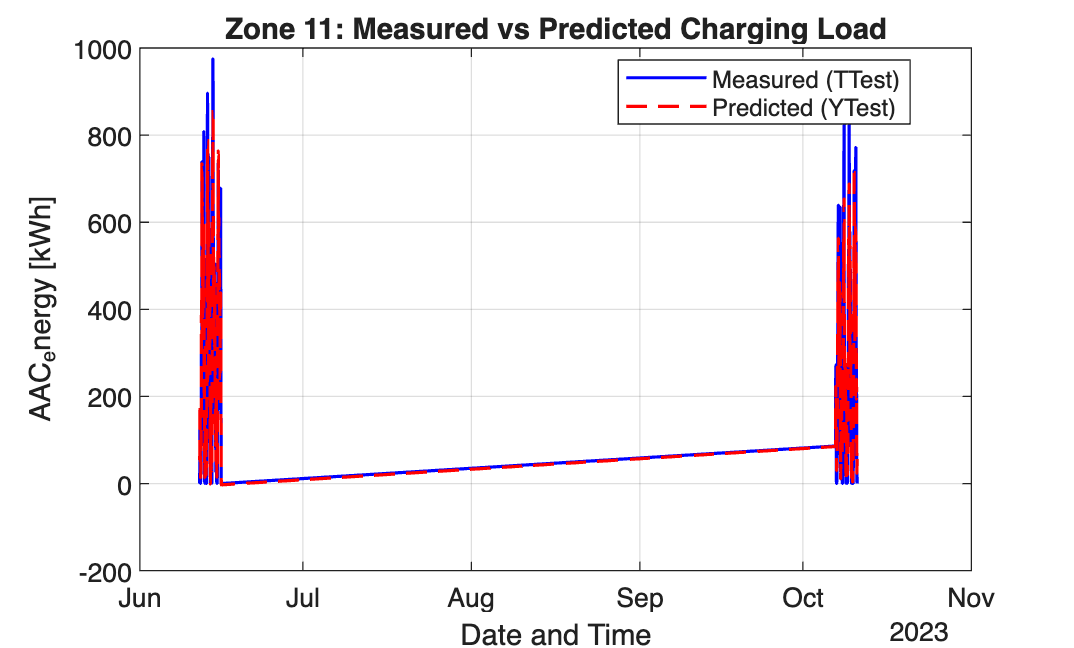

figure
plot(testData.timestamps, TTestReal, "b-", LineWidth=1.2)
hold on
plot(testData.timestamps, YTest, "r--", LineWidth=1.2)
legend(["Measured (TTest)" "Predicted (YTest)"], Location="best")
xlabel("Date and Time")
ylabel("AAC_energy [kWh]")
title(sprintf("Zone %d: Measured vs Predicted Charging Load", zoneId))
grid on

Compute the forecast residuals and inspect their sample autocorrelation across 20 lags. If the values stay inside the confidence bounds, the errors carry no remaining temporal memory.

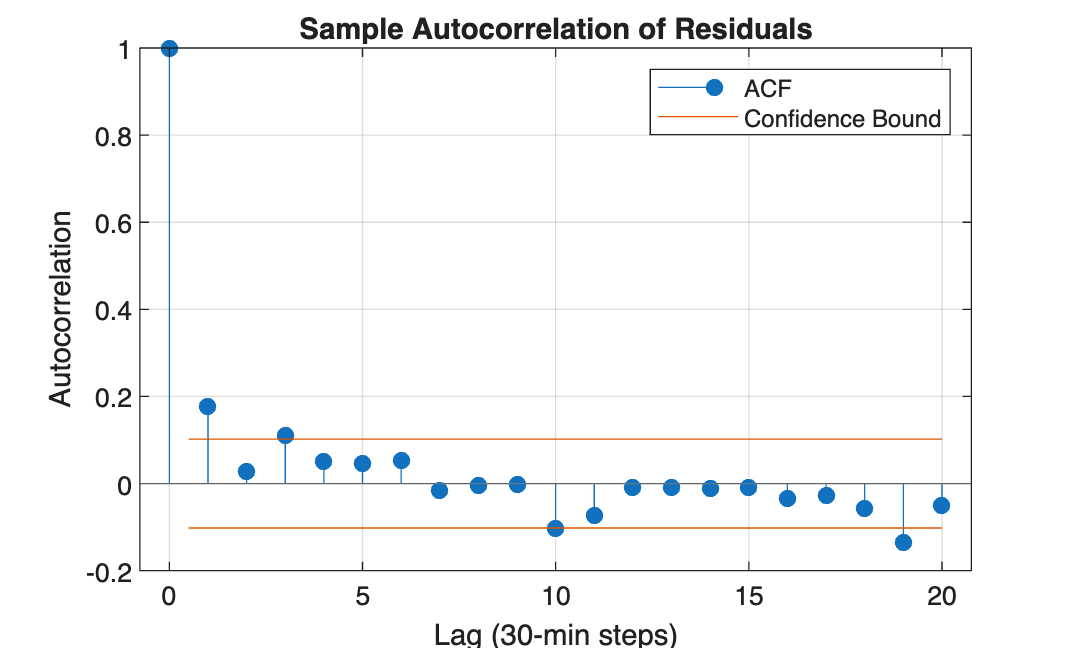

residuals = double(TTestReal - YTest);
figure
autocorr(residuals, NumLags=20)
title("Sample Autocorrelation of Residuals")
xlabel("Lag (30-min steps)")
ylabel("Autocorrelation")
grid on

Run the Ljung-Box test to verify whether the residuals behave as white noise.

lagsToTest = 10;
[h, pValue, stat, cValue] = lbqtest(residuals, Lags=lagsToTest);

fprintf("Ljung-Box Q-stat: %.2f (Critical: %.2f), p-value: %.4f\n", stat, cValue, pValue);

Ljung-Box Q-stat: 24.47 (Critical: 18.31), p-value: 0.0065


if h == 0
    disp("Fail to reject H0: Residuals are consistent with white noise.");
else
    disp("Reject H0: Residuals exhibit remaining autocorrelation.");
end

Reject H0: Residuals exhibit remaining autocorrelation.


## Save Net

Save the trained network and evaluation metrics to a timestamped file to preserve results without overwriting previous runs.

timestamp = string(datetime("now", "Format", "yyyyMMdd_HHmm"));
modelDir = fullfile("models", "LSTM", sprintf("Zone%d", zoneId));
if ~exist(modelDir, "dir")
    mkdir(modelDir);
end
modelFile = fullfile(modelDir, sprintf("LSTM_Zone%d_RMSE%.1f_%s.mat", zoneId, testRMSE, timestamp));
save(modelFile, "LSTMnet", "normParams", "predictorNames", "testRMSE");
fprintf("Model saved: %s\n", modelFile);

Model saved: models/LSTM/Zone11/LSTM_Zone11_RMSE95.8_20260908_2325.mat
